# Online Payment System Simulator

The simulator considers the simulation of an Online payment system that processes transaction through two main components:

- a Front-End(FE)

- a Database(DB)

Payment requests arrive according to a Poisson process with rate λ. Each request must first be processed by the FE and then by the DB.

The system has fault toleranche mechanisms for which:

- The FE is a 1 out of 2 redudant module. Which means that a single FE is sufficient to handle the traffic and the system cannot accept new requests only when both FEs fail. The repairing procedure is started immediately as an FE fails.

- The DB is a single critical point of failure, no redundances and if it fails the system cannot process requests. The DB is though protected by a checkpointing and recovery mechanism. It performs periodic checkpoints to save its state inside stable storage. If the DB fails during a checkpoint, upon restart it must recover data from the last completed checkpoints. During recovery time the DB is unavailable.

The system moreover has a finite waiting queue of size K of requests waiting for the FE and if the queue is full new requests get rejected. 

# Design system state

Considering the system, we first want to design the system state that describes the operating states in the simulator. 

So, we want to consider all the information which is necessary to know what happens next for each instant of the simulator. 

Analysing the system we know that each FE can have 3 states:

- working/up

- busy/working and serving

- not working/down

We want to keep trace of the number of FEs which are working and which are busy. we do not need the knowledge of the down FEs since that can be computed by max of FEs - n of working FEs.

state.feUp = [1,1]; %number of FEs currently in working state
state.feBusy = [0,0]; %number of FEs currently busy with a costumer

Now, another important element to design the system state is knowing how many costumers are waitining in the queue, considering that we have a maximum dimension for the queue, after which subsequent requests would get rejected.

state.nQueue=0; %max value for the queue will be K=20

The last and most important element to describe the system state is the DB, which has 2 important considerations:

- It can be working normally

- it can be Checkpointing and operating

- It can be in Recoverning, which means it can't accept any request and needs to recover the most recent finished checkpoint.

The DB can be in recoving both in normal and checkpointing but the recovery point will be different. 

Other than that the DB can be serving a request or not.

state.dbState = 'normal'; %the other states ban be 'checkpointing', 'recovering' 
state.dbBusy = false; %turn to true once it accepts a request and needs to elaborate it.
state.clock = 0.0;

After defining the single elements componing the minimum elements which are able to describe completely the state of the system, we can finally identify the overall system state at initial conditions as follows:

state

state = struct with fields:
       feUp: [1 1]
     feBusy: [0 0]
     nQueue: 0
    dbState: 'normal'
     dbBusy: 0
      clock: 0


# Dependent and Indipendent events

Now we want to make sure di visualize which are the dependent and indipendent events in our system.

Considering how it evolves, we can classify the indipendent events (which are those events that are generated exogenously from the system, and that can potentially happen at any given time) as:

- Request arrivial

- Failure of FE 1

- Failure of FE 2

- Failure of DB

- Checkpoint start of DB

These events will be present only based on their own distribution as they are auto-generated.

Dependent events are instead events that are generated from other events happening inside our system, In our case, these events are:

- FE finishes with the request (sends it to the DB)

- FE got repaired (get's back to a working state)

- DB finished saving the checkpoint (DB goes back to serving the pending requests)

- DB finished recovery (goes back from not functioning to functioning correctly)

- DB finished serving request (frees itself for the next request)

Let's now create the simulation

 **Simulation parameters**

We are defining the metrics in hours since, otherwise, the simulation will be extremely dense of requests in time and the computation will be extremely expensive.

%arrival of payment requests
params.lam= 100;
%maximum length of the queue waiting for the FE to serve them
params.k = 20;
%rate of the starting between each checkpoint for the DB system
params.tau= 0.01388;
%mean of checkpoint recovering with the exponential distribution
params.roInv= 200;
%duration distribution of the checkpoint
params.sigInv= 5;
%service time of FE
params.mu_feInv = 0.2;
%service time of DB
params.mu_dbInv= 0.5;
%mean of the exponential distribution of the front-end lifetime
%params.gamma_feInv = 24; %24 in hours  
params.gamma_feInv = 864;
%mean of the exponential distribution of the repair time of the FE
params.delta_feInv = 18; %30 min
%rate of the DB failures    
%params.gamma_dbInv = 168; %7 days
params.gamma_dbInv = 6048;
TE = 100000; %fake simulation time just as placeholder

# How the state changes when an event occurs

Considering all the events cited before, we can identify how the state will change for each event.

To do so, we consider starting with the initial system state defined before, which is

state

state = struct with fields:
       feUp: [1 1]
     feBusy: [0 0]
     nQueue: 0
    dbState: 'normal'
     dbBusy: 0
      clock: 0


**New request arrival**

%now we can consider a new request arriving. We can make function for each
%of these situations
function [updated_state, updated_metrics, updated_futureEventList] = new_request(state, metrics, futureEventList, params)

            ev.e = 'NewArrival'; 
            ev.t = state.clock + exprnd(1/params.lam);
            ev.slot= NaN;
            ev.arrivalTime = NaN;

            futureEventList = insertEvent(futureEventList, ev);
 
            systemDown = (state.feUp(1,1)==0 && state.feUp(1,2) == 0);
 
            if systemDown
                metrics.lostUnavail = metrics.lostUnavail + 1;
 
            elseif state.feBusy(1,1) ==0 && state.feUp(1,1) == 1
                % Assign to the first free FE slot
                state.feBusy(1,1) = 1;
                
                slot = 'FE1';
                ev.e = 'fromFEtoDB'; 
                ev.t = state.clock + exprnd(params.mu_feInv); 
                ev.slot = slot;
                ev.arrivalTime = state.clock;
                futureEventList = insertEvent(futureEventList, ev);
            
            elseif state.feBusy(1,2) ==0 && state.feUp(1,2) == 1
                % Assign to the first free FE slot
                state.feBusy(1,2) = 1;
               
                slot = 'FE2';
                ev.e = 'fromFEtoDB'; 
                ev.t = state.clock + exprnd(params.mu_feInv); 
                ev.slot = slot;
                ev.arrivalTime = state.clock;
                futureEventList = insertEvent(futureEventList, ev);

            elseif state.nQueue < params.k
                state.nQueue   = state.nQueue + 1;
                metrics.queueArrT(end+1) = state.clock; 
                
            elseif state.nQueue >= params.k
                metrics.lostBuffer = metrics.lostBuffer + 1;
            end

    updated_state = state;
    updated_metrics = metrics;
    updated_futureEventList = futureEventList;
end

we then have to take in consideration the event of the failure of the FEs

**Failure of FE1 or FE2**

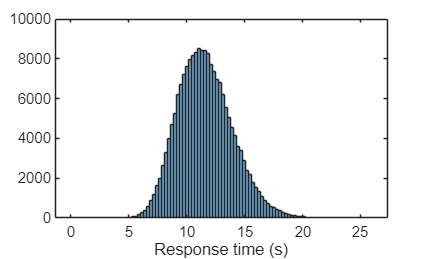

function [updated_state, updated_metrics, updated_futureEventList]= feFailure(state, metrics, futureEventList, slot, params)
    if strcmp(slot, 'FE1')

        if state.feUp(1,1) == 1
            state.feUp(1,1) = 0;
    
            % If this FE was busy, its request is lost
            if state.feBusy(1,1) == 1

                
                metrics.lostUnavail = metrics.lostUnavail + 1;
                state.feBusy(1,1) = 0;
                % Cancel the corresponding fromFEtoDB event
                futureEventList = removeEventsBySlot(futureEventList, 'fromFEtoDB', 'FE1');
                metrics.dbQueueArrT = removeEventsBySlot(metrics.dbQueueArrT,'RequestServed', 'FE1');
            end
    
            % If both FEs are now down, drain the wait queue
            if state.feUp(1,1) == 0 && state.feUp(1,2) ==0
                metrics.lostUnavail = metrics.lostUnavail + state.nQueue;
                state.nQueue = 0;


=================== RISULTATI CON INTERVALLI DI CONFIDENZA (95%) ===================


                metrics.queueArrT = [];

Throughput medio:       1.90 req/s          IC: [1.88, 1.91]


            end

Loss buffer medio:      97.6925 req/s         IC: [97.6186, 97.7665]


Loss unavail medio:     0.3992 req/s         IC: [0.3174, 0.4809]


        end

Mean response time:     11.6085 s         IC: [11.5968, 11.6203]


    elseif strcmp(slot, 'FE2')

        if state.feUp(1,2) == 1
            state.feUp(1,2) = 0;

            % If this FE was busy, its request is lost
            if state.feBusy(1,2) == 1
                metrics.lostUnavail = metrics.lostUnavail + 1;
                state.feBusy(1,2) = 0;
                % Cancel the corresponding fromFEtoDB event
                futureEventList = removeEventsBySlot(futureEventList, 'fromFEtoDB', 'FE2');
                metrics.dbQueueArrT = removeEventsBySlot(metrics.dbQueueArrT, 'RequestServed','FE2');
            end
    
            % If both FEs are now down, drain the wait queue
            if state.feUp(1,1) == 0 && state.feUp(1,2) ==0
                metrics.lostUnavail = metrics.lostUnavail + state.nQueue;
                state.nQueue = 0;
                metrics.queueArrT = [];
            end
        end
        % Repair starts immediately; remember which slot to restore
    end
    % Reschedule the next failure for this same slot
    % (only meaningful once it's repaired, but scheduling it now
    %  is harmless — BackToWorkFE does NOT reschedule it again)
    ev.e = 'BackToWorkFE'; 
    ev.t = state.clock + exprnd(params.delta_feInv); 
    ev.slot = slot;
    ev.arrivalTime = NaN;
    futureEventList = insertEvent(futureEventList, ev);

    
    updated_state = state;
    updated_metrics = metrics;
    updated_futureEventList = futureEventList;
end



**Failure of DB**

%now we want to consider what happens in case of DB failure
% Handle the DB failure scenario
function [updated_state, updated_metrics, updated_futureEventList] = dbFailure(state, metrics, futureEventList, params)

    % Request in service is lost
    if state.dbBusy
        futureEventList = removeEvents(futureEventList, 'RequestServed');
        metrics.lostUnavail = metrics.lostUnavail + 1;
        state.dbBusy  = false;
        if ~isempty(metrics.dbQueueArrT)
            numLost = length(metrics.dbQueueArrT);
            metrics.lostUnavail = metrics.lostUnavail + numLost;
            for i = 1:length(metrics.dbQueueArrT)
                if strcmp(metrics.dbQueueArrT(i).slot,'FE1')
                    state.feBusy(1,1) = 0;
                else   
                    state.feBusy(1,2) = 0;
                end
            end
            metrics.dbQueueArrT = [];
        end
    end


    state.dbState = 'recovering';


    futureEventList = removeEvents(futureEventList, 'CheckpointEnd');
    futureEventList = removeEvents(futureEventList, 'CheckpointStart');

    

    ev.e = 'BackToWorkDB'; 
    ev.t = state.clock + exprnd(params.roInv);
    ev.slot= NaN;
    ev.arrivalTime = NaN;
    futureEventList = insertEvent(futureEventList, ev);
    updated_state = state;
    updated_metrics = metrics;
    updated_futureEventList = futureEventList;

end

Next event is the starting of a checkpoint for the DB

**DB Checkpoint Event**

function  [updated_state, updated_metrics, updated_futureEventList] = dbCheckpointStart(state, metrics, futureEventList, params)

    state.dbState = 'checkpointing';
    ev.e = 'CheckpointEnd'; 
    ev.t = state.clock + exprnd(params.sigInv);
    ev.slot= NaN;
    ev.arrivalTime = NaN;
    futureEventList = insertEvent(futureEventList, ev);

    updated_state = state;
    updated_futureEventList = futureEventList;
    updated_metrics = metrics; 
end



**FE1 and FE2 repaired Event**

function  [updated_state, updated_metrics, updated_futureEventList] = FERepaired(state, metrics, futureEventList, currentEvent, params)

    if strcmp(currentEvent.slot, 'FE1')
        state.feUp(1,1) = 1; %FE1 back to operational
        % Pull a new request back to correct form
        ev.e = 'FEFailure'; 
        ev.t = state.clock + exprnd(params.gamma_feInv); 
        ev.slot = currentEvent.slot;
        ev.arrivalTime = NaN;
        futureEventList = insertEvent(futureEventList, ev);
        if state.nQueue > 0 && state.feBusy(1,1) == 0
    
            state.nQueue  = state.nQueue - 1;
            state.feBusy(1,1) = 1;
        
            ev.e = 'fromFEtoDB'; 
            ev.t = state.clock + exprnd(params.mu_feInv);
            ev.slot = 'FE1';
            ev.arrivalTime = metrics.queueArrT(1);
            metrics.queueArrT = metrics.queueArrT(2:end);
            futureEventList = insertEvent(futureEventList, ev);
        end
    elseif strcmp(currentEvent.slot,'FE2')
        state.feUp(1,2) = 1; %FE2 back to operational
        ev.e = 'FEFailure'; 
        ev.t = state.clock + exprnd(params.gamma_feInv); 
        ev.slot = currentEvent.slot;
        ev.arrivalTime = NaN;
        futureEventList = insertEvent(futureEventList, ev);

       % Pull a new request back to correct form
        if state.nQueue > 0 && state.feBusy(1,2) == 0

            state.nQueue  = state.nQueue - 1;
            state.feBusy(1,2) = 1;
        
            ev.e = 'fromFEtoDB'; 
            ev.t = state.clock + exprnd(params.mu_feInv); 
            ev.slot = 'FE2';
            ev.arrivalTime = metrics.queueArrT(1);
            metrics.queueArrT = metrics.queueArrT(2:end);
            futureEventList = insertEvent(futureEventList, ev);
        end
    end
    
    updated_state = state;
    updated_futureEventList = futureEventList;
    updated_metrics = metrics;
end


**From FE to DB Event**

function  [updated_state, updated_metrics, updated_futureEventList] = fromFEtoDB(state, metrics, futureEventList, currentEvent, params)

           

    if strcmp(state.dbState,'recovering')
        % if the DB is unavailable, we consider the request lost
        % after being completed by the FE
        metrics.lostUnavail = metrics.lostUnavail + 1;
        if strcmp(currentEvent.slot, 'FE1')
             if state.nQueue > 0 && state.feUp(1,1)==1
                state.nQueue = state.nQueue - 1;
                ev.e = 'fromFEtoDB'; 
                ev.t = state.clock + exprnd(params.mu_feInv); 
                ev.slot = 'FE1';
                ev.arrivalTime = metrics.queueArrT(1);
                metrics.queueArrT = metrics.queueArrT(2:end);
                futureEventList = insertEvent(futureEventList, ev);
            else
                state.feBusy(1,1) = 0;
            end
        elseif strcmp(currentEvent.slot, 'FE2')
            if state.nQueue > 0 && state.feUp(1,2)==1
                state.nQueue = state.nQueue - 1;
                ev.e = 'fromFEtoDB'; 
                ev.t = state.clock + exprnd(params.mu_feInv); 
                ev.slot = 'FE2';
                ev.arrivalTime = metrics.queueArrT(1);
                metrics.queueArrT = metrics.queueArrT(2:end);
                futureEventList = insertEvent(futureEventList, ev);
            else
                state.feBusy(1,2) = 0;
            end
        end

    elseif ~state.dbBusy
        %if instead the DB is available and not busy, the request
        %will get handled by the DB
        state.dbBusy  = true;
        
        ev.e = 'RequestServed'; 
        ev.t = state.clock + exprnd(params.mu_dbInv);
        ev.slot= NaN;
        ev.arrivalTime = currentEvent.arrivalTime;
        futureEventList = insertEvent(futureEventList, ev);
        
        if strcmp(currentEvent.slot, 'FE1')
            if state.nQueue > 0 && state.feUp(1,1)==1
                state.nQueue  = state.nQueue - 1;
                ev.e = 'fromFEtoDB'; 
                ev.t = state.clock + exprnd(params.mu_feInv); 
                ev.slot = currentEvent.slot;
                ev.arrivalTime = metrics.queueArrT(1);
                metrics.queueArrT = metrics.queueArrT(2:end);
                futureEventList = insertEvent(futureEventList, ev);

            else
                state.feBusy(1,1) = 0;
            end

        elseif strcmp(currentEvent.slot, 'FE2')
            if state.nQueue > 0 && state.feUp(1,2)==1
                state.nQueue  = state.nQueue - 1;
                ev.e = 'fromFEtoDB'; 
                ev.t = state.clock + exprnd(params.mu_feInv); 
                ev.slot = currentEvent.slot;
                ev.arrivalTime = metrics.queueArrT(1);
                metrics.queueArrT = metrics.queueArrT(2:end);
                futureEventList = insertEvent(futureEventList, ev);

            else
                state.feBusy(1,2) = 0;
            end
        end
    else
        %if the DB is busy, so it cannot accept the request, since
        %we do not have any queue for the DB, we consider that the
        %request will be inserted in an infinite db queue
        postponedRequest = currentEvent;
        postponedRequest.e = 'RequestServed';
        postponedRequest.t = state.clock;
        postponedRequest.slot = currentEvent.slot;
        metrics.dbQueueArrT = insertEvent(metrics.dbQueueArrT, postponedRequest);
        
    end
     
    updated_state = state;
    updated_metrics = metrics;
    updated_futureEventList = futureEventList;
end

**DB Recovered Event**

function  [updated_state, updated_metrics, updated_futureEventList] = recoveredDB(state, metrics, futureEventList, checkpoint, params)

    state.dbState = 'normal';
            
    %recovers the state of the DB at the end of the last checkpoint
    if ~isempty(fieldnames(checkpoint)) && isfield(checkpoint,'eventValid')&& checkpoint.eventValid
        state.dbBusy  = checkpoint.dbBusy;
    else
        state.dbBusy = false;
    end
    %scheduling both next failure and next checkpoint, since all previously
    %scheduled checkpoints were cancelled
    ev.e = 'DBFailure';      
    ev.t = state.clock + exprnd(params.gamma_dbInv); 
    ev.slot= NaN;
    ev.arrivalTime = NaN;
    futureEventList = insertEvent(futureEventList, ev);
    ev.e = 'CheckpointStart';
    ev.t = state.clock + exprnd(1/params.tau);
    ev.slot= NaN;
    ev.arrivalTime = NaN;
    futureEventList = insertEvent(futureEventList, ev);
    if state.dbBusy && checkpoint.eventValid
        checkpoint.savedEvent.t = state.clock + exprnd(params.mu_dbInv);
        futureEventList = insertEvent(futureEventList, checkpoint.savedEvent);
    end
    updated_state = state;
    updated_metrics = metrics;
    updated_futureEventList = futureEventList;

end

**DB Checkpoint End**

function  [updated_state, updated_metrics, updated_futureEventList, checkpoint] = dbCheckpointEnd(state, metrics, futureEventList, params)
    if strcmp(state.dbState,'checkpointing')
        state.dbState = 'normal';
        
        checkpoint.dbBusy = state.dbBusy;
        checkpoint.savedEvent = getEventsFromList(futureEventList, 'RequestServed');
        if state.dbBusy
            checkpoint.eventValid = true;
        else
            checkpoint.eventValid = false;
        end
    end
    ev.e = 'CheckpointStart'; 
    ev.t = state.clock + exprnd(1/params.tau);
    ev.slot= NaN;
    ev.arrivalTime = NaN;
    futureEventList = insertEvent(futureEventList, ev);

    updated_state = state;
    updated_metrics = metrics;
    updated_futureEventList = futureEventList;
end

**Initialization of metrics**

nRun = 10;
allThroughput   = zeros(1, nRun);
allLossBuffer   = zeros(1, nRun);
allLossUnavail  = zeros(1, nRun);
allRespTime     = zeros(1, nRun);
for i= 1:nRun
%we are interested in the mean response time, in the throughput, loss rate
%due to buffer overflow and loss rate due to system unavailability
    metrics.nCompleted=0; %number of request that got completed
    metrics.lostBuffer=0; %number of requests lost because of the buffer
    metrics.lostUnavail=0; %number of requests lost because the system was unavailable
    metrics.responseTimes=[];
    metrics.queueArrT=[];
    metrics.dbQueueArrT = []; 

**State and Future Event list initialization**

    state.feUp = [1,1];
    state.feBusy = [0,0];
    state.nQueue = 0;
    state.dbState = 'normal';
    state.dbBusy = false;
    checkpoint = struct();
    %feInService = [0, 0];
    
    %adding the termination event to our simulator
    ev.e = 'end';
    ev.t = TE;
    ev.slot= NaN;
    ev.arrivalTime = NaN;
    futureEventList = ev;
    %adding the first arrival
    ev.e = 'NewArrival';
    ev.t = exprnd(1/params.lam);
    ev.slot= NaN;
    ev.arrivalTime = NaN;
    futureEventList = insertEvent(futureEventList, ev);
    
    %adding first checkpoint event
    ev.e = 'CheckpointStart';
    ev.t = exprnd(1/params.tau);
    ev.slot= NaN;
    ev.arrivalTime = NaN;
    futureEventList = insertEvent(futureEventList, ev);
    
    %adding first FE failure
    ev.e = 'FEFailure';
    ev.t = exprnd(params.gamma_feInv);
    ev.slot = 'FE1';
    ev.arrivalTime = NaN;
    futureEventList = insertEvent(futureEventList, ev);
    
    ev.e = 'FEFailure';
    ev.t = exprnd(params.gamma_feInv);
    ev.slot = 'FE2';
    ev.arrivalTime = NaN;
    futureEventList = insertEvent(futureEventList, ev);
    %first db failure
    ev.e = 'DBFailure';
    ev.t = exprnd(params.gamma_dbInv);
    ev.slot= NaN;
    ev.arrivalTime = NaN;
    futureEventList = insertEvent(futureEventList, ev);

**Simulation main block**

    currentEvent = futureEventList(1);
    futureEventList = futureEventList(2:end);
    while (strcmp(currentEvent.e, 'end')~=1)
        state.clock = currentEvent.t;
        switch currentEvent.e
            case 'NewArrival'
                [state, metrics, futureEventList]= new_request(state, metrics, futureEventList, params);
            case 'FEFailure'
                [state, metrics, futureEventList] = feFailure(state, metrics, futureEventList, currentEvent.slot, params);
            case 'DBFailure'
                [state, metrics, futureEventList] = dbFailure(state,metrics, futureEventList, checkpoint, params);
            case 'CheckpointStart'
                [state, metrics, futureEventList]= dbCheckpointStart(state, metrics, futureEventList, params);
            case 'fromFEtoDB'
                [state, metrics, futureEventList]= fromFEtoDB(state, metrics, futureEventList, currentEvent, params);
            case 'BackToWorkFE'
                [state, metrics, futureEventList]= FERepaired(state, metrics, futureEventList, currentEvent, params);
            case 'CheckpointEnd'
                [state, metrics, futureEventList, checkpoint]= dbCheckpointEnd(state, metrics, futureEventList, params);
            case 'BackToWorkDB'
                [state, metrics, futureEventList]= recoveredDB(state, metrics, futureEventList, checkpoint, params);
            case 'RequestServed'
                if ~isnan(currentEvent.arrivalTime)
                    rt = state.clock - currentEvent.arrivalTime;
                end

                metrics.nCompleted = metrics.nCompleted + 1;
                metrics.responseTimes(end+1) = rt;
                %since the first request completed after checkpoint would
                %be the one saved, we can define that the event saved
                %should not be taken back again
                checkpoint.eventValid = false;
                if ~isempty(metrics.dbQueueArrT)
                    % DB rimane busy e serve la prossima richiesta in coda
                    oldRequest = metrics.dbQueueArrT(1);
                    oldRequest.t = state.clock + exprnd(params.mu_dbInv);
                    metrics.dbQueueArrT = metrics.dbQueueArrT(2:end);
                    futureEventList = insertEvent(futureEventList, oldRequest);
                    if strcmp(oldRequest.slot,'FE1')
                        if state.nQueue > 0 && state.feUp(1,1)==1
                        state.nQueue  = state.nQueue - 1;
                        ev.e = 'fromFEtoDB'; 
                        ev.t = state.clock + exprnd(params.mu_feInv); 
                        ev.slot = oldRequest.slot;
                        ev.arrivalTime = metrics.queueArrT(1);
                        metrics.queueArrT = metrics.queueArrT(2:end);
                        futureEventList = insertEvent(futureEventList, ev);
    
                        else
                        state.feBusy(1,1) = 0;
                        end
                    elseif strcmp(oldRequest.slot,'FE2')
                        if state.nQueue > 0 && state.feUp(1,2)==1
                        state.nQueue  = state.nQueue - 1;
                        ev.e = 'fromFEtoDB'; 
                        ev.t = state.clock + exprnd(params.mu_feInv); 
                        ev.slot = oldRequest.slot;
                        ev.arrivalTime = metrics.queueArrT(1);
                        metrics.queueArrT = metrics.queueArrT(2:end);
                        futureEventList = insertEvent(futureEventList, ev);
    
                        else
                        state.feBusy(1,2) = 0;
                        end
                    end
                        
                else
                    % coda DB vuota, DB torna idle
                    state.dbBusy = false;
                end
        end
        %futureEventList
        currentEvent = futureEventList(1);
        futureEventList = futureEventList(2:end);
    end
    
    allThroughput(i)  = metrics.nCompleted / TE;
    allLossBuffer(i)  = metrics.lostBuffer / TE;
    allLossUnavail(i) = metrics.lostUnavail / TE;
    if ~isempty(metrics.responseTimes)
        allRespTime(i) = mean(metrics.responseTimes);
    end
end

results.throughput    = metrics.nCompleted / TE;
results.loss_buffer   = metrics.lostBuffer / TE;
results.loss_unavail  = metrics.lostUnavail / TE;
results.mean_resp_time = mean(metrics.responseTimes);

figure;
histogram(metrics.responseTimes, 100);
xlabel('Response time (s)');

%Calculate the Confidence Bounds of the metrics obtained
alpha = 0.05; % Livello di significatività (95% confidenza)
% Calcolo per il Throughput
[mean_Th, ic_Th] = ICCalculator(allThroughput, alpha);
% Calcolo per la perdita a causa del Buffer pieno
[mean_LB, ic_LB] = ICCalculator(allLossBuffer, alpha);
% Calcolo per la perdita a causa di sistema non disponibile
[mean_LU, ic_LU] = ICCalculator(allLossUnavail, alpha);
% Calcolo per il Tempo di Risposta Medio
[mean_RT, ic_RT] = ICCalculator(allRespTime, alpha);
fprintf('\n=================== RISULTATI CON INTERVALLI DI CONFIDENZA (95%%) ===================\n');
fprintf('Throughput medio:       %.2f req/s          IC: [%.2f, %.2f]\n', mean_Th, ic_Th(1), ic_Th(2));
fprintf('Loss buffer medio:      %.4f req/s         IC: [%.4f, %.4f]\n', mean_LB, ic_LB(1), ic_LB(2));
fprintf('Loss unavail medio:     %.4f req/s         IC: [%.4f, %.4f]\n', mean_LU, ic_LU(1), ic_LU(2));
fprintf('Mean response time:     %.4f s         IC: [%.4f, %.4f]\n', mean_RT, ic_RT(1), ic_RT(2));
fprintf('====================================================================================\n');

function [media, ic] = ICCalculator(vettore_dati, alpha)
    n = length(vettore_dati);
    media = mean(vettore_dati);
    dev_std = std(vettore_dati);
    
    % Valore critico t di Student per n-1 gradi di libertà
    t_critico = tinv(1 - alpha/2, n - 1);
    
    % Margine di errore
    margine_errore = t_critico * (dev_std / sqrt(n));
    
    % Output dell'intervallo [limite_inferiore, limite_superiore]
    ic = [media - margine_errore, media + margine_errore];
end
    